# ME 419 Lab 1

#### Julia Fay & Aiden Taylor

## Exercise 1

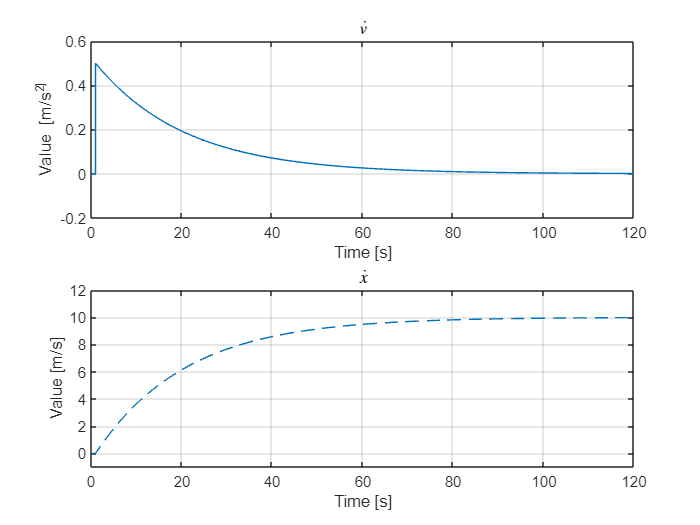

subplot (2,1,1);
x = sim('Lab1_419_simul');  %run simulink simulation
plot(x.tout, x.simout(:,1));%plot acceleration
grid on;
title('$\dot{v}$', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Value [m/s^2]')
axis([0 120 -0.2 0.6])
subplot(2,1,2);             %plot velocity
plot(x.tout, x.simout(:,2), '--')
grid on;
title("$\dot{x}$", 'Interpreter', 'latex');
xlabel('Time [s]')
ylabel('Value [m/s]')
axis([0 120 -1 12])

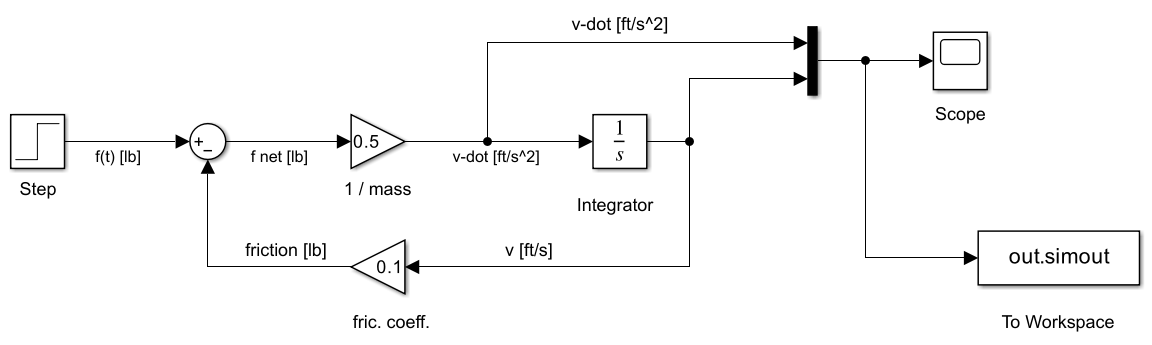

snapshotModel('Lab1_419_simul') %output simulink image

## Exercise 3

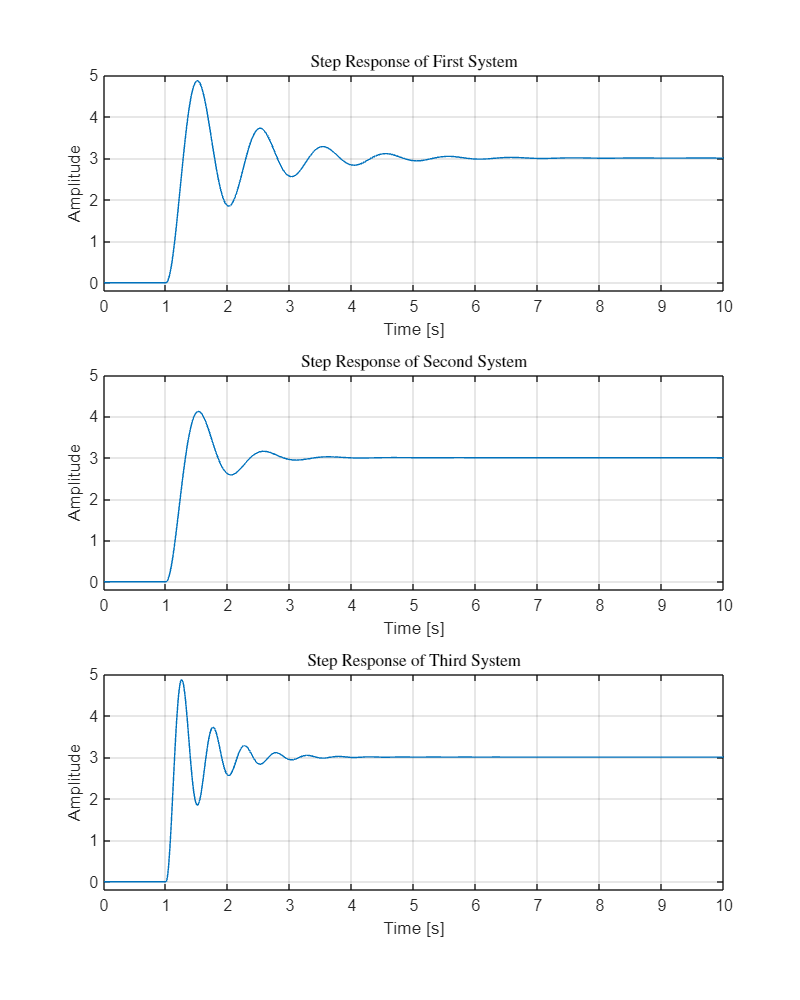

fig1 = figure();
fig1.Position(3:4) = [560*3 420*5]; %scale subplot
y = sim('Lab1_419_simul3');         %run simulink
subplot (3,1,1);                    %plot sys 1
plot(y.tout, y.simout(:,1));
grid on;
title('Step Response of First System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

subplot(3,1,2);                     %plot sys 2
plot(y.tout, y.simout1(:,1));
grid on;
title('Step Response of Second System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

subplot(3,1,3);                     %plot sys 3
plot(y.tout, y.simout2(:,1));
grid on;
title('Step Response of Third System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

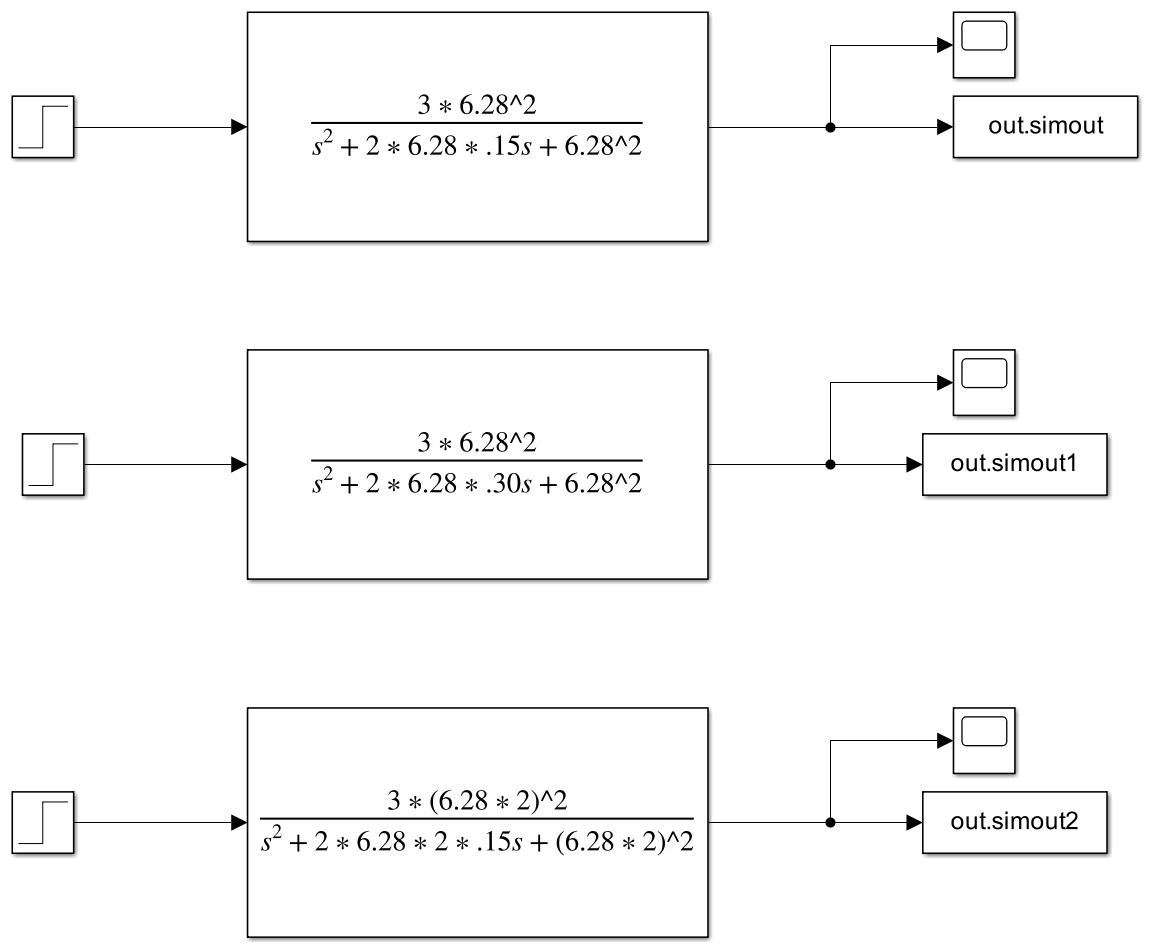

snapshotModel('Lab1_419_simul3')

## Exercise 4

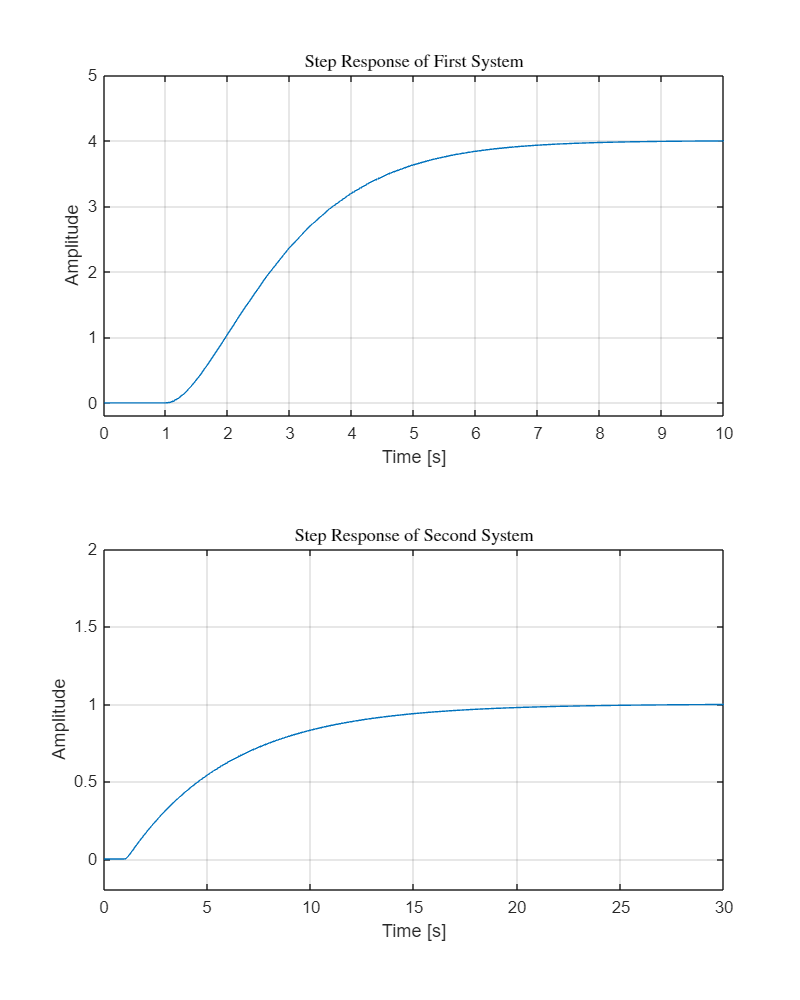

fig1 = figure();
fig1.Position(3:4) = [560*3 420*5]; %scale subplot
z = sim('Lab1_419_simul4');         %run simulink
subplot (2,1,1);                    %plot sys 1
plot(z.tout, z.simout(:,1));
grid on;
title('Step Response of First System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])
subplot (2,1,2);                    %plot sys 1
plot(z.tout, z.simout1(:,1));
grid on;
title('Step Response of Second System', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 30 -0.2 2])

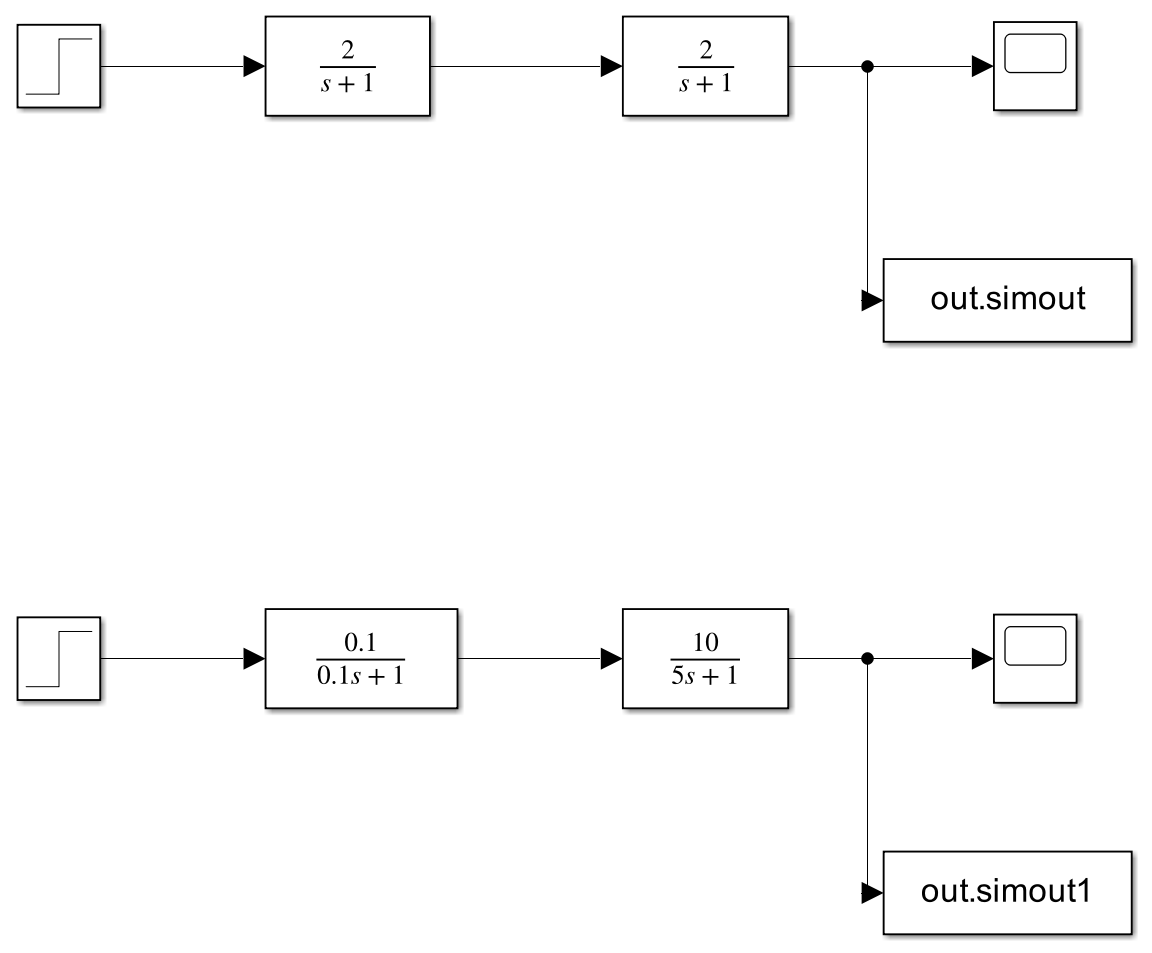

snapshotModel('Lab1_419_simul4')